# Homework 10/16

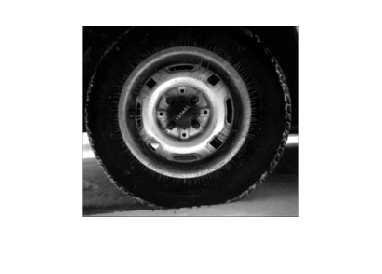

I =  imread('tire.tif');
figure;  imshow(I);

### CLAHE

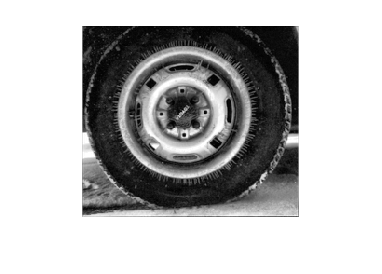

A = adapthisteq(I, "Distribution", "uniform");    % uniform
figure; imshow(A);

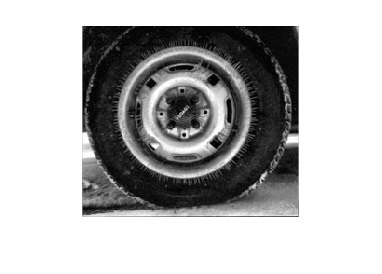

B = adapthisteq(I, "Distribution", "exponential");   % exponential
figure; imshow(B);

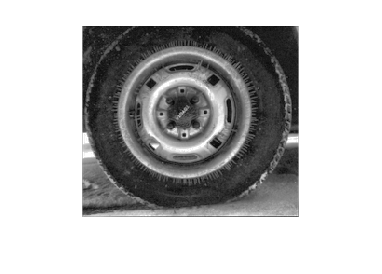

C = adapthisteq(I, "Distribution", "rayleigh");   % rayleigh
figure; imshow(C);

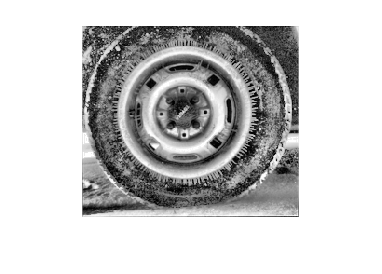

D = adapthisteq(I, "ClipLimit", 0.1);
figure; imshow(D);

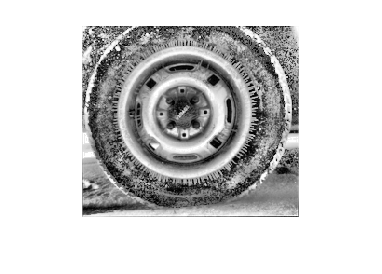

E = adapthisteq(I, "ClipLimit", 0.5);
figure; imshow(E);

F = adapthisteq(I, "ClipLimit", 1);
figure; imshow(F);

可以看到用不同Distribution調整完之後的圖雖然有些不同，但共通點是他們的輪胎還有輪框邊界都會變清楚，甚至有點調整過頭而變白的現象。

cliplimit的功能我不太確定，但看圖片跟上課講義感覺cliplimit越高的時候我們會把越大範圍的值取出來調整，導致圖片上的noise也被增強，但是可以透過調整參數來減少增強noise的問題。